# Get Started with Problem-Based Optimize Live Editor Task

This example script helps you to use the problem-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints:

Minimize ${\rm rosenbrock}(x,y,a)=a(y - x^2)^2 + (1-x)^2$ subject to the constraint $x^2+y^2\le 1$, where $a=100$ and the initial point $x0$ has $x=-2,\ y=2$. Also, impose the bounds $-3\le x\le 3$, $-2\le y\le 9$.

The code for the objective function appears at the end of this script.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point components `x0x` and `x0y` and scale `a` for the optimization.

x0x = -2;
x0y = 2;
a = 100;

Z_top=[5;5;5;5;5;5;5;pi/3];
Z_bot=-Z_top;

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

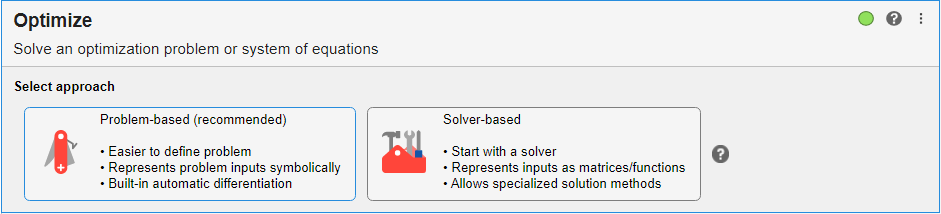

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
x2 = optimvar("x",8,1,"LowerBound",Z_bot,"UpperBound",Z_top);

% Set initial starting point for the solver
initialPoint.x = Z_bot;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@V,x2,P,Rset);

% Define problem constraints
problem.Constraints = constraintFcn(x2,Z_top,Z_bot);

% Set nondefault solver options
options = optimoptions("fmincon","PlotFcn","optimplotfval");

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x

	minimize :
       ((((x.' .* (((sin((2 .* x(8))) ./ 4) + 0.5) .* arg21)) * extraParams{4}) * x) + arg23)

       where:

           arg4 = ((((2333 .* cos(x(8)).^2) ./ 1812) + ((4145 .* sin(x(8)).^2) ./ 1812)) - 2.2875);
           arg9 = ((((2333 .* cos(x(8)).^2) ./ 1812) + ((4145 .* sin(x(8)).^2) ./ 1812)) - 2.2875);
           arg11 = (((x.' .* (((sin((2 .* x(8))) ./ 4) - 0.5) .* arg4)) * extraParams{1}) * x);
           arg15 = ((((2333 .* cos(x(8)).^2) ./ 1812) + ((4145 .* sin(x(8)).^2) ./ 1812)) - 1.2875);
           arg17 = ((((x.' .* ((-((sin((2 .* x(8))) ./ 4) + 0.5)) .* arg9)) * extraParams{2}) * x) + arg11);
           arg21 = ((((2333 .* cos(x(8)).^2) ./ 1812) + ((4145 .* sin(x(8)).^2) ./ 1812)) - 1.2875);
           arg23 = ((((x.' .* ((-((sin((2 .* x(8))) ./ 4) - 0.5)) .* arg15)) * extraParams{3}) * x) + arg17);

Solving problem using fmincon.

Feasible point with lower objective function value found.



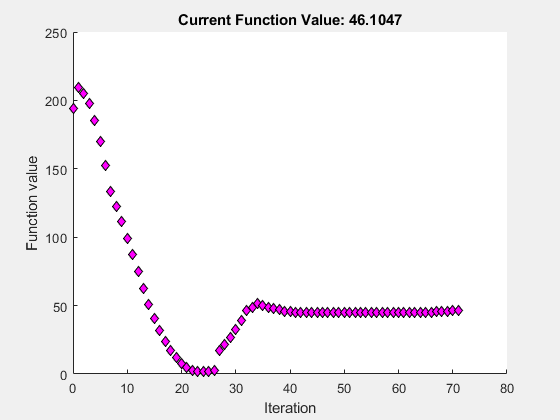


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);


% Display results
solution

solution = struct with fields:
    x: [8×1 double]


reasonSolverStopped

reasonSolverStopped =     StepSizeBelowTolerance


objectiveValue

objectiveValue = 46.1047


% Clear variables
clearvars x2 initialPoint options reasonSolverStopped objectiveValue

## Interpret Results

The task calls `solve`, which calls `fmincon` to solve the problem. The top of the task shows that the solution is returned in the `solution` structure. The reported solution, `x = 0.7864` and `y = 0.6177`, satisfies the constraint $x^2+y^2\le 1$, as you can see in the following calculation.

solution.x^2 + solution.y^2                                     

The solver reports exit condition `OptimalSolution` when it stops. To interpret this condition, look at the `exitflag` [output of `solve`](docid:optim_ug.mw_cedf587e-dc58-476c-a675-a44b82bff7c5) for the `fmincon` solver. The description states "First-order optimality measure is less than options.OptimalityTolerance, and maximum constraint violation is less than options.ConstraintTolerance." In other words, the solution is a feasible local minimum.

The objective function value at the solution is 0.0457. This is the smallest objective function value among feasible points.

## Helper Functions

This code creates the `rosenbrock` helper function.

function objective = rosenbrock(x,y,a)
% This function should return a scalar representing an optimization objective.

% Example: Concession stand profit
% revenue = 3*soda + 5*popcorn + 2*candy;
% cost = 1*soda + 2*popcorn + 0.75*candy;
% objective = revenue - cost; % profit

% Edit the lines below with your calculations.
objective = a*(y - x^2)^2 + (1 - x)^2;
end

*Copyright 2021 The MathWorks, Inc.*


function objective = V(x,P,Rset)
% This function should return a scalar representing an optimization objective.

% Example: Concession stand profit
% revenue = 3*soda + 5*popcorn + 2*candy;
% cost = 1*soda + 2*popcorn + 0.75*candy;
% objective = revenue - cost; % profit

% Edit the lines below with your calculations.
summ=0;
psi=x(8);
h= [ (sin(2*psi)/4 - 1/2)*((2333*cos(psi)^2)/1812 + (4145*sin(psi)^2)/1812 - 4145/1812);
-(sin(2*psi)/4 + 1/2)*((2333*cos(psi)^2)/1812 + (4145*sin(psi)^2)/1812 - 4145/1812);
-(sin(2*psi)/4 - 1/2)*((2333*cos(psi)^2)/1812 + (4145*sin(psi)^2)/1812 - 2333/1812);
 (sin(2*psi)/4 + 1/2)*((2333*cos(psi)^2)/1812 + (4145*sin(psi)^2)/1812 - 2333/1812)];
for j=Rset
    summ = x'*h(j)*P{j}*x + summ;
end
objective = summ;
end

function constraints = constraintFcn(x,Z_top,Z_bot)
% This function should return a vector of optimization constraints.
% Constraints are two expressions separated by a comparison operator (<=, >=, ==).

% Note, ALL comparison operators must be the same in a constraint vector.
% To use differing comparison operators, create a separate function for each operator.

% Example: Factory production capacity constraint
% factory1Cap =  500*x + 200*y + 100*z;
% factory2Cap = 1000*x + 100*y + 400*z;
% constraints(1) = factory1Cap + factory1Cap <= 500;

% Edit the lines below with your calculations.
constraints(1) = prod(x-Z_top)*prod(x-Z_bot) == 0;
end
